# PROGETTO ZERO INTERLEAVING


%
% Lo script deve ricostruire una sequenza x_n a partire da una sua versione "zero interleaved" indicata con y_n
% in cui ogni M campioni sono inseriti M-1 zeri (al posto dei campioni originari)

% Esempio:
% sequenza originaria                       x_n = 1,2,3,4,5,6,7,8,9,10...
% sequenza zero_interleaved (fattore M = 3)  y_n= 1,0,0,4,0,0,7,0,0,10...

% La sequenza di partenza x_n ha 400 campioni ed è fornita nel file zerointerleaving.mat

% Si richiede che lo script Matlab esegua le seguenti operazioni:

% - generi la sequeza zero-interleaved y_n con M variabile (M = 2,3,...),
% cioé si deve poter scegliere il numero di campioni (M-1) da azzerare.

% - permetta di scegliere la posizione dei campioni non nulli, es. si chiede la
% possibilità di generare M possibili sequenze con campioni non nulli in posizione
% Mk, Mk+1, Mk+2, ... Mk+(M-1) con k = 0,1,2,...

% - rappresenti graficamente la sequenza x_n e le sequenze y_n (zero_interleaved)
% nel dominio del tempo e delle frequenze (trasformata discreta di Fourier).
%
% - rappresenti graficamente nel dominio del tempo e delle frequenze il filtro impiegato per la ricostruzione
% della sequenza x_n

% - rappresenti graficamente la sequenza originaria x_n e la sua versione
% ricostruita, mostrando che la sequenza ricostruita è la stessa qualunque
% sia la scelta della posizione dei campioni non nulli (purché non vi siano fenomeni di alias).

% - permetta di valutare il massimo valore di M che non produce distorsione del segnale ricostrutito.

% Strutturare lo script Matlab in modo tale che possa essere rapidamente adattato per gestire sequenze in ingresso
% diverse da quella assegnata (es. diverso numero di campioni).
% Definire in modo chiaro le variabili utilizzate e commentare sinteticamente i vari passi dello script.


## **START**

close all;
%clear;
clc;
%prompt = ('Inserisci nome file :  ');
%nome_file = input (prompt, 's');
%load (nome_file);
%si può trovare un modo per caricare direttamente in una variabile?
load zerointerleaving.mat
%y = x; %crea un secondo vettore per non modificare sequenza originale
dim = length(x);
M = input('Inserisci M: ');
f_s = 1/M; %frequenza di campionamento, ma potremmo toglierla perché non serve
%f  = -f_s : 1 : f_s;


## **ZERO-INTERLEAVING**

y_n = zeros(M,dim); %crea una matrice di zeri contenente le M sequenze lungo le righe
Yf_n = y_n; %copia la matrice creata in quella che sarà la trasformata
for j = 1:M %ciclo per creare sequenze campionate
    i = j;
    while i<dim+1
        y_n(j,i) = x(i);
        i = i+M;
    end
end


## **TRASFORMAZIONI** 

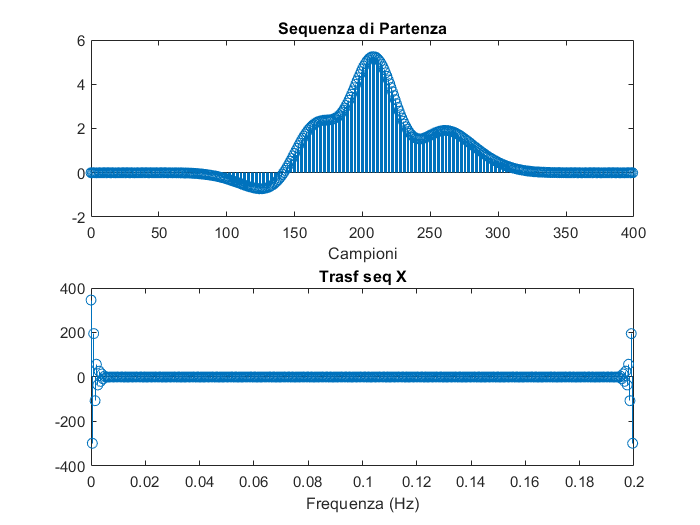

n = (0:dim-1);
To = dim*M;
DF = 1/To;
Xf=fft(x);
figure
subplot(2,1,1)
stem (n,x);
xlabel ('Campioni')
title('Sequenza di Partenza')
pause
subplot(2,1,2)
stem (DF*n,real(Xf));
xlabel ('Frequenza (Hz)')
title('Trasf seq X')

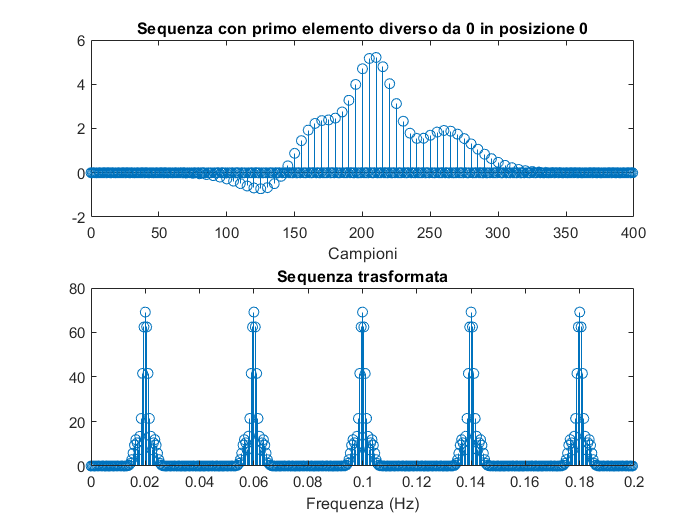

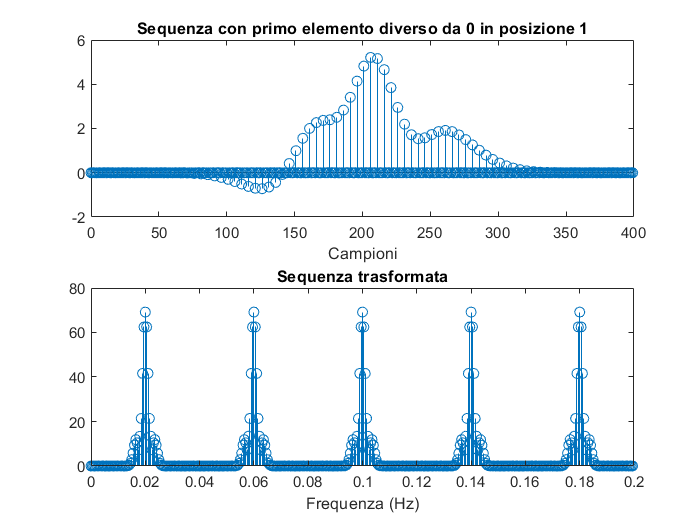

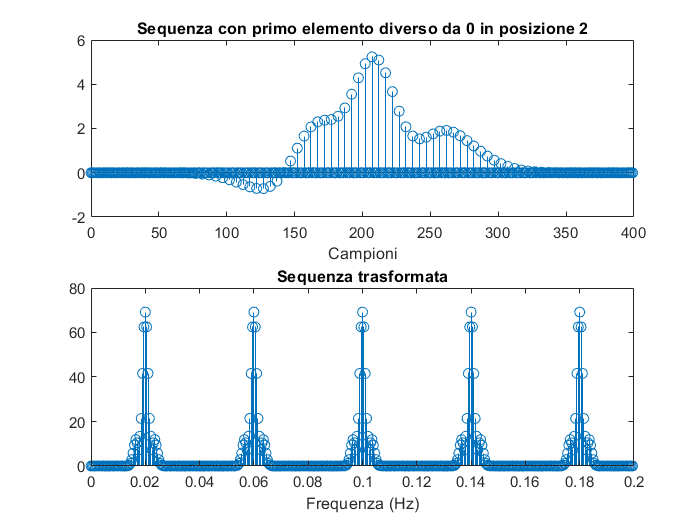

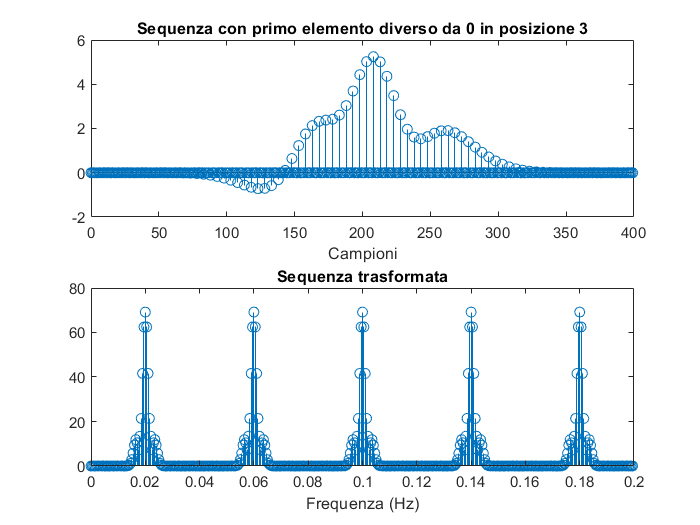

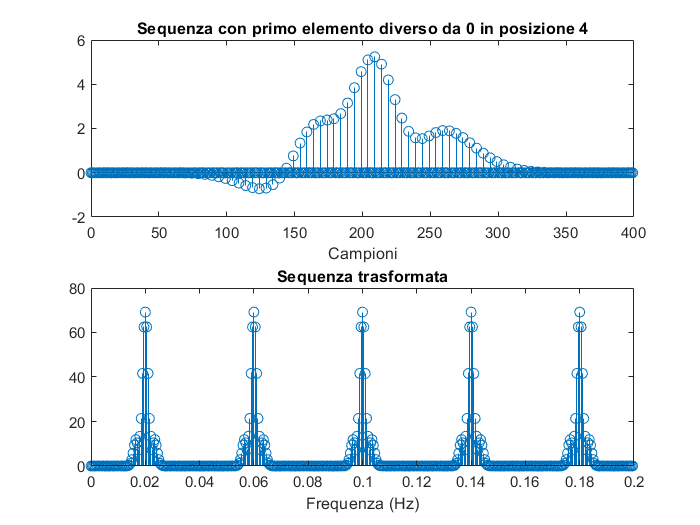

pause
for k = 1:M
    titolo = 'Sequenza con primo elemento diverso da 0 in posizione %d';
    pos = k-1; %indice di posizione che viene riportato nel grafico
    %Yf_n(k,:) = fft(y_n(k,:));
    Yf_n(k,:) = fftshift(abs(fft(y_n(k,:)))); 
    %non ho ancora capito bene come funzioni la fttshift, 
    %ma se fatta sul valore assoluto della trasformata dà 
    %graficamente il risultato sperato
    figure
    subplot(2,1,1)
    stem(n,y_n(k,:));
    xlabel ('Campioni')
    title(sprintf(titolo,pos))
    subplot(2,1,2)
    stem(DF*n,real(Yf_n(k,:)));
    xlabel ('Frequenza (Hz)')
    title('Sequenza trasformata')
    pause
end

## **FILTRO**

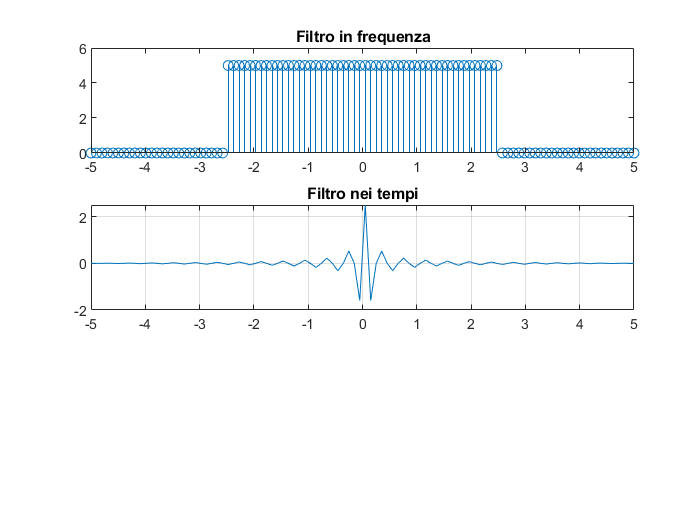

figure
%f = -dim/2 : 1 : (dim/2)-1;
f = linspace(-M,M); %credo sia da rivedere questo intervallo 
% su cui si basano costruzione e rappresentazione del filtro
filtro = M*rectangularPulse(-M/2,M/2,f);
% syms fx
%filtro_t = ifft (filtro);
filtro_t = ifftshift(ifft(filtro));
subplot (3,1,1)
stem(f,real(filtro));
title('Filtro in frequenza')
subplot (3,1,2)
plot(f,real(filtro_t));
grid on;
title('Filtro nei tempi')

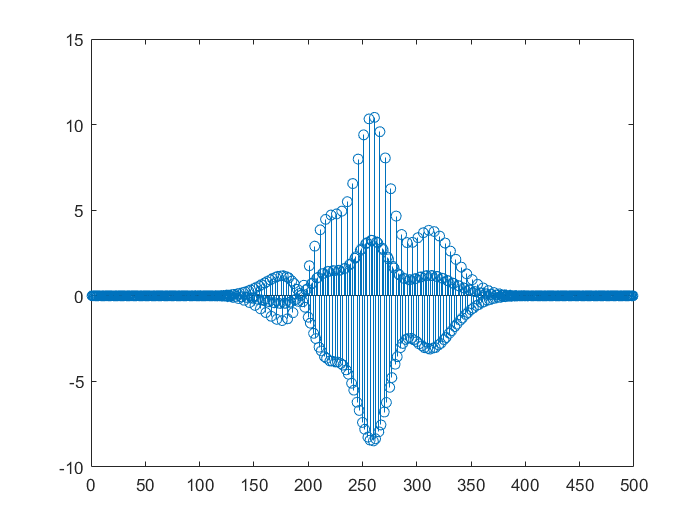

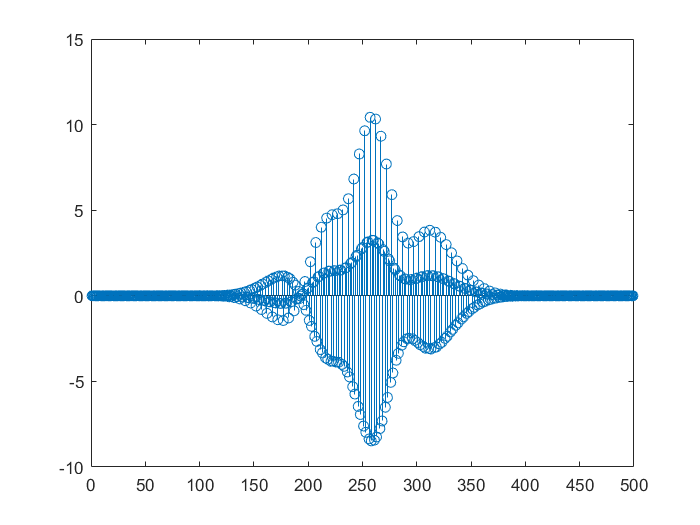

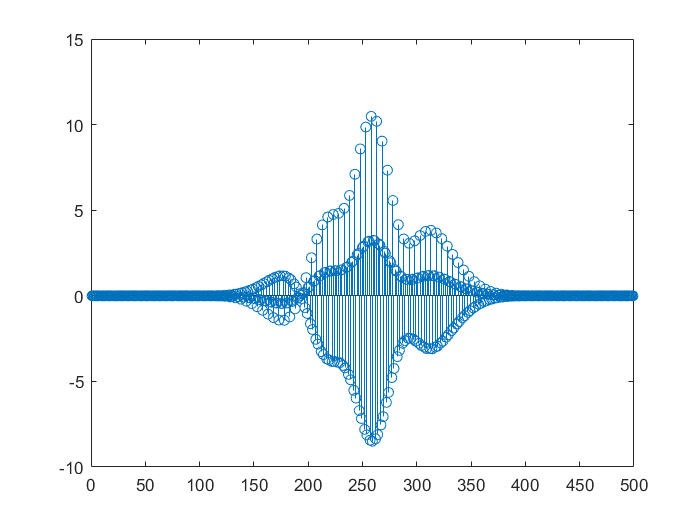

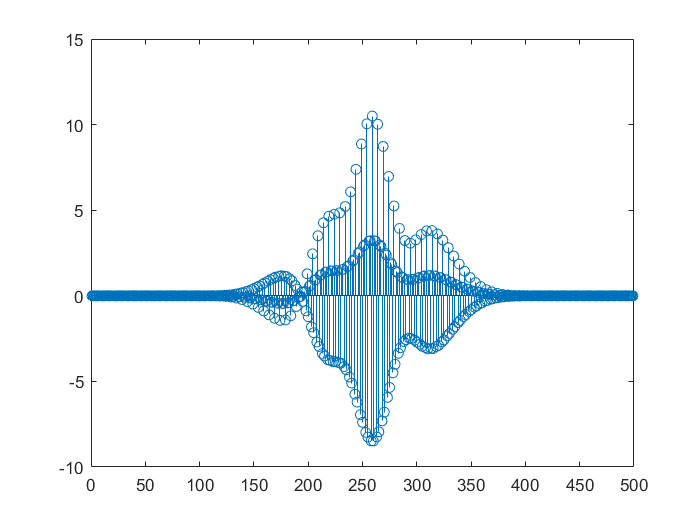

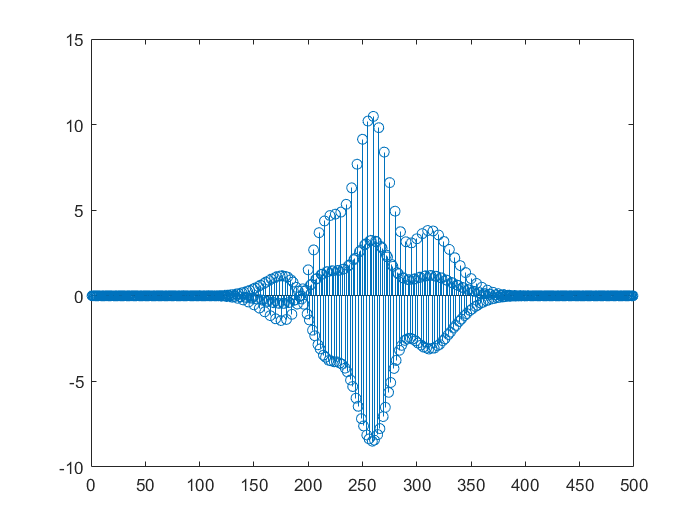

%subplot (3,1,3)
for i=1:M
    figure
    %z = Yf_n(i,:).*real(filtro);
    z = conv(y_n(i,:),real(filtro_t));
    %la convoluzione ancora è da controllare,
    %ma almeno la forma c'è; 
    %il picco è un po' più in alto
    %Non torna il numero di campioni del plot, 
    %dovrebbe essere 400 anche dopo la convoluzione
    stem(z);
end

%%

%creare filtro rettangolo, tenerlo discreto, fare trasformata discreta.

## **ADD ?**

%error('M scelto non rispetta il teorema del campionamento!');
